## Note: this file will take a preprocessed EEG dataset, determine an appropriate baseline, and feed it into a Gaussian Mixture Model (GMM)

## read in filtered data

allEDFs_filtered = allEDFs;

## baseline mean determination

% find index of first instance of "intubat" (intubation)
index1 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'intubat', 'IgnoreCase',true));
onset1 = allEDFs_filtered.annotations{'EEG'}.Onset(index1(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset1);
intubation_Index = find(index)

intubation_Index = 259585


% find index of first instance of "incis" (incision)
index2 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'incis', 'IgnoreCase',true));
onset2 = allEDFs_filtered.annotations{'EEG'}.Onset(index2(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset2);
incision_Index = find(index)

incision_Index = 678529

% run function to determine start index for each EEG channel
channels = {'EEGFp1_Cp3','EEGFpz_Cp3', 'EEGCp3_T3', 'EEGT3_O1', 'EEGFp2_Cp4', 'EEGFpz_Cp4', 'EEGCp4_T4', 'EEGT4_O2'}

channels = 1×8 cell array
    {'EEGFp1_Cp3'}    {'EEGFpz_Cp3'}    {'EEGCp3_T3'}    {'EEGT3_O1'}    {'EEGFp2_Cp4'}    {'EEGFpz_Cp4'}    {'EEGCp4_T4'}    {'EEGT4_O2'}


table_size = size(allEDFs_filtered.data{'EEG'}); % determine size of table for for loop
start_index = nan(1,table_size(1,2));
for k = 1:length(channels)
    start_index(1,k) = baseline_mean(table_size, allEDFs_filtered, channels(1,k));
end
start_index % check for baseline start

start_index =         4737        4737        4737        4737        4738        4737        4737        4737



% check that there is not a lot of variance between start_index values. too
% large of a difference could indicate a problem with the baseline
% determination values and would need to be evaluated on a case-by-case
% basis
diffs = diff(start_index);
diffs = max(abs(diffs(diffs >= 0)));
if (diffs > 5)
    error("large variance among baseline start indices detected. largest difference was determined to be " + diffs)
end



% determining the baseline for all channels
baseline_preIntubation = nan(1,8);
baseline_postIntubation = nan(1,8);
baseline_Total = nan(1,8);
for i = 1:table_size(1,2)
    baseline_preIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):intubation_Index, channels(1,i)},'omitnan');  
    baseline_postIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index, channels(1,i)},'omitnan');  
    baseline_Total(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):incision_Index, channels(1,i)},'omitnan');
end
baseline_preIntubation

baseline_preIntubation =     0.0242   -0.0625   -0.0328    0.0620    0.1133   -0.0207   -0.0643   -0.0449


baseline_postIntubation

baseline_postIntubation =    -0.0609   -0.0633   -0.0908   -0.0123   -0.0346   -0.1700    0.0036   -0.0044


baseline_Total

baseline_Total =    -0.0387   -0.0631   -0.0757    0.0071    0.0040   -0.1311   -0.0141   -0.0150



% 15 second windows
    % data from baseline regions is divided into 15 second windows and then
    % the mean is calculated to create one 15 second array per channel


% window_inds = start_index(1,1):window:intubation_Index
% window_inds = max(start_index):window_size:intubation_Index;
% baseline_window = zeros(window_size, length(channels(1,:)), length(window_inds)); % pre allocate for speed
% for i = 1:length(window_inds)
%     baseline_window(:,:,i) = allEDFs_filtered.data{'EEG'}{window_inds(i):window_inds(i)+window_size-1, :};
%     % TODO = remove section where number is repeated excessively
% end
% mean_baseline = mean(baseline_window, 3, 'omitnan')
% 
% 
% preintubation_baseline_window = baseline_windowed(start_index, intubation_Index, allEDFs_filtered, window_size, channels)
% postintubation_baseline_window = baseline_windowed(intubation_Index, incision_Index, allEDFs_filtered, window_size, channels)
% total_baseline_window = baseline_windowed(start_index, incision_Index, allEDFs_filtered, window_size, channels)

% mean(allEDFs_filtered.data{'EEG'}{start_index(1,1):intubation_Index,1},'omitnan')
% allEDFs_filtered.data{'EEG'}{intubation_Index + 1,2}


rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;


  window_inds = max(start_index):window_size:intubation_Index; % finding window indices 15 seconds apart
    
    % create and populate 3D array from baseline range
    baseline_windows = zeros(window_size, length(channels(1,:)), length(window_inds));
    for i = 1:length(window_inds)
        baseline_windows(:,:,i) = allEDFs_filtered.data{'EEG'}{window_inds(i):window_inds(i)+window_size-1, :};
    end
    
    % average values to return one baseline window
   % mean_baseline = mean(baseline_windows, 3, 'omitnan');

## analysis 

% from hospital team: abnormal events are annotated as alerts when duration
% of event exceeds 1 min

% from hospital team: abnormal events are observed when one or both
% hemishperes stray from baseline



% window entire study after baseline
window_inds_analysis = intubation_Index+1:window_size:size(allEDFs_filtered.data{'EEG'}(:,1));
window_analysis = zeros(window_size, length(channels(1,:)), length(window_inds_analysis));    % preallocating for speed
for i = 1:length(window_inds_analysis)-1
    window_analysis(:,:,i) = allEDFs_filtered.data{'EEG'}{window_inds_analysis(i):window_inds_analysis(i)+window_size-1, :};
    % TODO = remove section where number is repeated excessively
end

% do either/both percentage change model or GMM in this area
    % can we feed the GMM the raw data or do we have to extract the
    % features from the raw data ourselves and feed it to the GMM






% add function that determines the GMM parameters from the baseline windows



%gm = fitgmdist(preintubation_baseline_window, 1) % how do we know how many components a GMM should be?

Unrecognized function or variable 'preintubation_baseline_window'.

%properties(gm); % list all properties for the GMM. Can be accessed using format "gm.NumVariables" (dot notation)
% for each 15 second window, for each channel compute delta (1-3Hz) theta
% (4-7Hz) alpha (8-12Hz) beta (13-20Hz) gamma (30-100Hz) (spectral) - 40 measurements for each window (40 X #15-second
% windows you have), then feed it into gaussian mixture model


% % compute fast fourier transform for baseline window
%transforms_baseline = fft(baseline_windows, 133, 3) % remove hard-coded second argument

% compute fast fourier transform of each window in the analysis portion





Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
L = length(window_analysis)

L = 1920

N = L % end point

N = 1920

f = (Fs*(0:((L-1)/2))/L); % frequency
transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

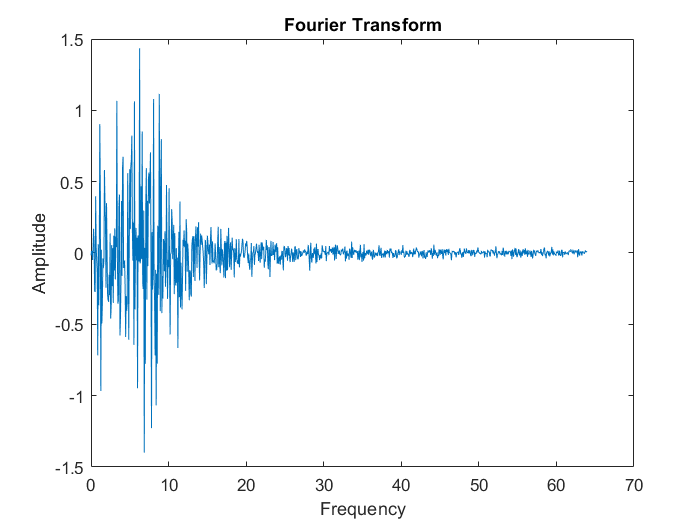

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform')

%delta = int(single_sided_transform(:,1,1),1,3)
%pspectrum(transforms_analysis(:,1,1), Fs)


% try to run bandpower function
% try 
%     for i = 1:size(window_analysis)(1,3)
%         delta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         theta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         alpha = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         beta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         gamma = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%     end
% catch ME
%     
% end
% z = fillmissing(window_analysis, 'movmedian', 10)
% delta = bandpower(window_analysis(:,:,4), Fs, [1 3])

% spectral bands
delta = spectral_bandpower(window_analysis, [1 3], Fs)

delta = 	1.0e+04 *

    0.0013    0.0018    0.0023    0.0010    0.0012    0.0026    0.0034    0.0020
    0.0011    0.0016    0.0026    0.0008    0.0024    0.0037    0.0037    0.0009
    0.0011    0.0018    0.0028    0.0009    0.0012    0.0016    0.0026    0.0015
    0.0015    0.0020    0.0026    0.0007    0.0021    0.0028    0.0026    0.0009
    0.0018    0.0028    0.0039    0.0014    0.0023    0.0035    0.0050    0.0011
    0.0022    0.0028    0.0047    0.0013    0.0030    0.0052    0.0065    0.0023
    0.0038    0.0051    0.0047    0.0016    0.0027    0.0045    0.0048    0.0012
    0.0033    0.0045    0.0070    0.0006    0.0021    0.0042    0.0094    0.0043
    0.0025    0.0036    0.0036    0.0026    0.0030    0.0042    0.0098    0.0146
    0.0021    0.0030    0.0024    0.0008    0.0018    0.0024    0.0034    0.0018


theta = spectral_bandpower(window_analysis, [4 7], Fs)

theta = 	1.0e+03 *

    0.0460    0.0745    0.0606    0.0161    0.0717    0.0895    0.0894    0.0133
    0.0577    0.0860    0.0865    0.0120    0.0898    0.1064    0.1177    0.0116
    0.0329    0.0466    0.0617    0.0122    0.0556    0.0839    0.0888    0.0123
    0.0529    0.0691    0.0848    0.0110    0.0588    0.0928    0.0931    0.0112
    0.0480    0.0629    0.0930    0.0155    0.0549    0.0812    0.1053    0.0138
    0.0661    0.0906    0.1085    0.0123    0.0944    0.1264    0.1594    0.0180
    0.0520    0.0785    0.0562    0.0145    0.0532    0.1122    0.0928    0.0175
    0.0570    0.0832    0.1281    0.0177    0.0748    0.0896    0.1361    0.0195
    0.0326    0.0428    0.0781    0.0183    0.0437    0.0601    0.1094    0.0351
    0.0246    0.0313    0.0623    0.0128    0.0301    0.0375    0.0663    0.0118


alpha = spectral_bandpower(window_analysis, [8 12], Fs)

alpha = 	1.0e+03 *

    0.0347    0.0502    0.0392    0.0050    0.0346    0.0659    0.0412    0.0067
    0.0824    0.1150    0.0761    0.0145    0.0802    0.1127    0.0579    0.0138
    0.1573    0.2196    0.1151    0.0218    0.1755    0.2936    0.1072    0.0133
    0.1583    0.2072    0.1225    0.0206    0.1320    0.1833    0.1141    0.0125
    0.1206    0.1962    0.1688    0.0237    0.1521    0.1916    0.1636    0.0284
    0.1293    0.1802    0.1462    0.0205    0.1431    0.2109    0.1423    0.0148
    0.0723    0.1053    0.0889    0.0187    0.0806    0.1233    0.0667    0.0154
    0.1216    0.1669    0.2086    0.0217    0.1413    0.2400    0.1762    0.0194
    0.0565    0.0828    0.0655    0.0222    0.0809    0.1028    0.0523    0.0205
    0.0349    0.0499    0.0482    0.0151    0.0405    0.0682    0.0472    0.0137


beta = spectral_bandpower(window_analysis, [13 20], Fs)

beta = 	1.0e+03 *

    0.0041    0.0054    0.0077    0.0011    0.0054    0.0084    0.0063    0.0016
    0.0044    0.0063    0.0087    0.0011    0.0070    0.0091    0.0102    0.0014
    0.0075    0.0091    0.0078    0.0017    0.0102    0.0151    0.0131    0.0024
    0.0074    0.0096    0.0109    0.0012    0.0114    0.0132    0.0099    0.0016
    0.0073    0.0109    0.0131    0.0018    0.0098    0.0135    0.0155    0.0021
    0.0089    0.0108    0.0142    0.0017    0.0102    0.0132    0.0106    0.0016
    0.0066    0.0095    0.0102    0.0021    0.0090    0.0144    0.0110    0.0022
    0.0101    0.0126    0.0145    0.0021    0.0148    0.0167    0.0182    0.0040
    0.0078    0.0109    0.0125    0.0012    0.0142    0.0196    0.0147    0.0024
    0.0058    0.0070    0.0070    0.0009    0.0069    0.0094    0.0076    0.0012


gamma = spectral_bandpower(window_analysis, [30 100], Fs) % function needs to be modified to take the highest value instead of 100, otherwise it wont run

Output argument "spectral_value" (and maybe others) not assigned during call to "spectral_bandpower".


    % Note: translated to function
% wind_analysis_size = size(window_analysis)

wind_analysis_size =         1920           8        1225


% caught_nans = {};
% frequency_band = [1 3];
% for i = 1:wind_analysis_size(1,3)
%     data = window_analysis(:,:,i);
%     try
%         delta(i,:) = bandpower(data, Fs, frequency_band);
%     catch
%         [rows, columns] = find(isnan(data));
%         caught_nans{i,1} = [rows columns];
%         [B, BG, BP] = groupcounts(caught_nans{i,1}(:,2));
%         
%         if (length(caught_nans{i,1}) > 200) % if total occurances of NaN values exceeds thresholds, go to next loop iteration
%             continue;
%         end
%         
%         if (isempty(BG(B>=50))) % if column of values has more than threshold number of NaN in a row, go to next loop iteration
%           continue;
%         end
%           
%           temp = fillmissing(data, 'movmedian', 100);
%           delta(i,:) = bandpower(temp, Fs, frequency_band);
%     end
% end
% delta

delta = 	1.0e+04 *

    0.0013    0.0018    0.0023    0.0010    0.0012    0.0026    0.0034    0.0020
    0.0011    0.0016    0.0026    0.0008    0.0024    0.0037    0.0037    0.0009
    0.0011    0.0018    0.0028    0.0009    0.0012    0.0016    0.0026    0.0015
    0.0015    0.0020    0.0026    0.0007    0.0021    0.0028    0.0026    0.0009
    0.0018    0.0028    0.0039    0.0014    0.0023    0.0035    0.0050    0.0011
    0.0022    0.0028    0.0047    0.0013    0.0030    0.0052    0.0065    0.0023
    0.0038    0.0051    0.0047    0.0016    0.0027    0.0045    0.0048    0.0012
    0.0033    0.0045    0.0070    0.0006    0.0021    0.0042    0.0094    0.0043
    0.0025    0.0036    0.0036    0.0026    0.0030    0.0042    0.0098    0.0146
    0.0021    0.0030    0.0024    0.0008    0.0018    0.0024    0.0034    0.0018


% catch exception for NaN values

%delta = bandpower(window_analysis(1:582 584:end,1,1), Fs, [1 3])

plot(window_analysis(575:585, :, 4))
xlim([6 9])
ylim([-50 30])
legend(channels)
plot(window_analysis(:, 6, 4))

% unknowns: estimating k; putting new data into a model to get probability
% that it fits the model -> (posterior function)

% start with one channel/one feature to get a sense of if its working
% properly    


%NOTE: GMM requires Statistics and Machine Learning Toolbox